% Definizione dei parametri
r = 0.4;
R = 6;
g = 9.81;
H = 4;
q10 = 1.2;
q30 = 0.5;
c = pi*r^2;
S = pi*R^2;

hi = [4, 5, 6];
e_i = [6, 2, 9];

a = c^2*g/(S*q10);
b = c^2*g/(S*(q10+q30));

h30 = H + 1/(2*g)*((q10+q30)/c)^2;
h20 = h30 + 1/(2*g)*(q10/c)^2;
h10 = h20 + 1/(2*g)*(q10/c)^2;

% Definizione matrici
A = [-a, a, 0; 
      a, -2*a, a; 
      0, a, -(a+b)]

A =    -0.0183    0.0183         0
    0.0183   -0.0365    0.0183
         0    0.0183   -0.0312


B = [1/S, 0; 
      0, 0; 
      0, 1/S];
C = [0, 0, 1]

C =      0     0     1


D = [0, 0]

D =      0     0


% Definisco il sistema in forma di stato
sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
             x1        x2        x3
   x1  -0.01826   0.01826         0
   x2   0.01826  -0.03653   0.01826
   x3         0   0.01826  -0.03115
 
  B = 
             u1        u2
   x1  0.008842         0
   x2         0         0
   x3         0  0.008842
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.




% autovalori in anello aperto
eig_ol = eig(A)

eig_ol =    -0.0576
   -0.0254
   -0.0029


% Controllabilità
Mc=ctrb(A,B); rMc=rank(Mc); 
if rMc==size(A)
    disp('system is fully controllable');
else
    disp('system is not fully controllable');
end

system is fully controllable


% Osservabilità
Mo=obsv(A,C); rMo=rank(Mo); 
if rMc==size(A)
    disp('system is fully observable');
else
    disp('system is not fully observable');
end

system is fully observable


% retroazione di stato
p1 = [-0.03, -0.001-0.001j, -0.001+0.001j]

p1 =   -0.0300 + 0.0000i  -0.0010 - 0.0010i  -0.0010 + 0.0010i


K1 = place(A,B,p1);

% osservatore di Luemberger
po = [-0.02, -0.2, -0.4]

po =    -0.0200   -0.2000   -0.4000


kd = place(A',C',po);
L = kd';

% Risposta libera del sistema con codizione iniziale non nulla quando il
% sistema è chiuso in retroazione con K1 ed L

sys_k1L = ss([A-B*K1, B*K1; zeros(size(A)), A-L*C],[B; zeros(size(B))], [C, zeros(size(C))], D);
[Y,T,X]=initial(sys_k1L, [hi e_i]);

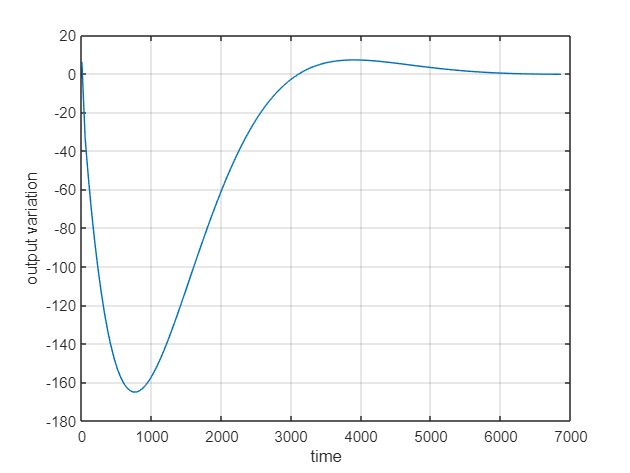

% Visualizzare l'uscita,  gli stati e gli errori di stima sugli stati
figure;
plot(T,Y), grid on; % plot of system output
xlabel('time'), ylabel('output variation')

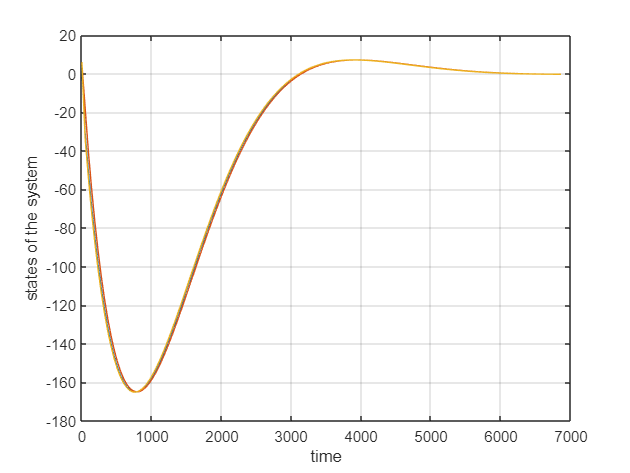


figure;
plot(T,X(:,1),T,X(:,2),T,X(:,3)), grid on; % plot of system output
xlabel('time'), ylabel('states of the system')

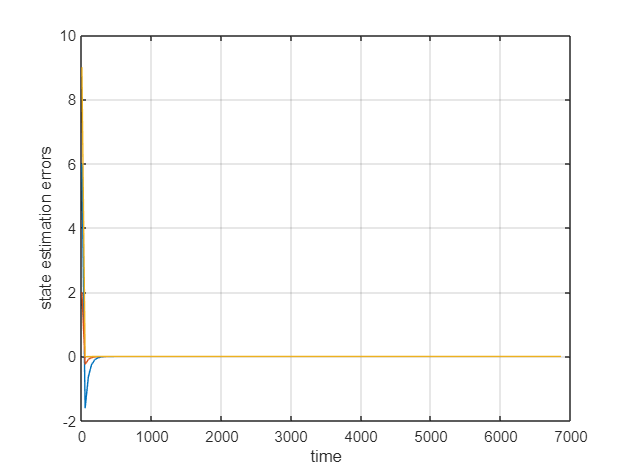


figure;
plot(T,X(:,4),T,X(:,5),T,X(:,6)), grid on; % state estimation error plot
xlabel('time'), ylabel('state estimation errors')

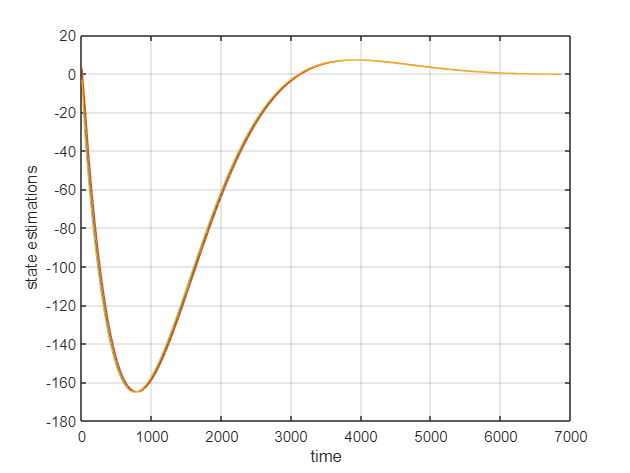


figure;
h_hat =X(:,1:3)-X(:,4:6); % state estimations
plot(T,h_hat(:,1),T,h_hat(:,2),T,h_hat(:,3)), grid on; % plot of the state estimations
xlabel('time'), ylabel('state estimations')